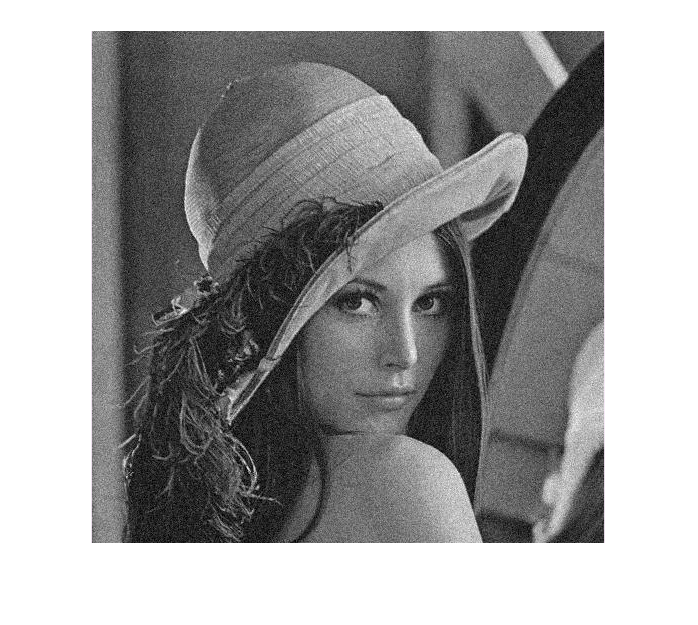

I=imread('D:\matlab_project\image_process\WEEK6HW\lena.jpg');
[m,n]=size(I);
new_I=I;
hmax=double(max(max(I)));
type=1;
imshow(I);

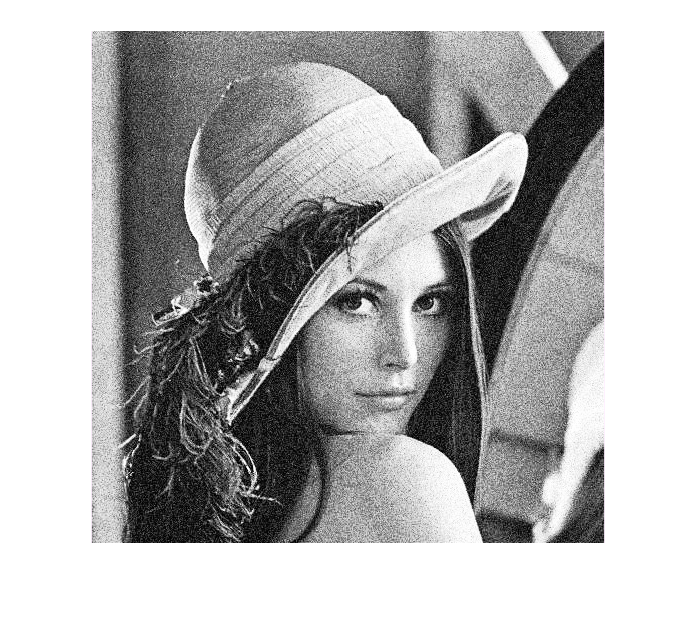

if type==1
    jsum=0;
    for i=0:255
        logic=(I==i);
        jsum=jsum+sum(logic(:));
        new_I(logic)=uint8(jsum*hmax/(m*n));
    end
else
    new_I=1;
end
imshow(new_I);